# 一维链在给定无序下的透射率

计算一维无序链的typical transmission与average transmission的差别

变量分别为长度和无序度

结论为typical 透射率$T_{\textrm{typ}} \left(\Gamma \;\right)=e^{\ln \langle T\rangle \;}$ 固定长度变化无序强度时，有$T_{\textrm{typ}} \left(\Gamma \;\right)=e^{-\alpha \;\Gamma {\;}^{2\;} }$的行为

而average透射率$T_{\textrm{ave}} \left(\Gamma \;\right)=\langle T\rangle \;$则没有这种行为

clear;
energyscale = 3;
N_point = 301;
Width = 1;
t = 1;
epsilon = 0;
eta = 1e-4;

U = 0;
omega = linspace(-energyscale,energyscale,N_point);

Accuracy = 1e-10;
%% 导线哈密顿量
H00 = epsilon * eye(Width) - t' * diag(ones(Width-1,1),-1) - t * diag(ones(Width-1,1),+1);
V = -t * eye(Width);
Iden = eye(Width);
tic;
Tr = 1;
VaryFlag = "Length";
if VaryFlag == "Disorder"
    Disorder = linspace(0,5,21);
    layer = 30;
    omega = 0;
else
    Disorder =3;
    layer = 1:10:200;
    omega = 0;
end

ave = 200;

## 计算格林函数与电导率

中心区哈密顿量

HCC = epsilon * eye(Width) - t' * diag(ones(Width-1,1),-1) - t * diag(ones(Width-1,1),+1);

G_00_Right = zeros(Width, Width, length(omega));
G_00_Left = zeros(Width, Width, length(omega));
Transmission = zeros(length(Disorder),length(omega),ave);

for ii = 1:length(omega)
    G_00_Right = SurfaceGreenFunction_V2_mex(H00, V, omega(ii), Accuracy);
    G_00_Left = SurfaceGreenFunction_V2_mex(H00, V', omega(ii), Accuracy);

    Sigma_L = SurfaceGreenFunction_SelfEnergy(G_00_Left, Tr*V');
    Sigma_R = SurfaceGreenFunction_SelfEnergy(G_00_Right, Tr*V);

    Gamma_L = SurfaceGreenFunction_Broadening(Sigma_L);
    Gamma_R = SurfaceGreenFunction_Broadening(Sigma_R);
    if VaryFlag == "Disorder"
        for jj = 1:length(Disorder)
            for kk = 1: ave
                G_Centre_Ret = RecursiveGreenFunction_1L(HCC, V, layer, omega(ii), Sigma_L, Sigma_R, eta, 'Onsite_disorder', Disorder(jj), 0);
                Transmission(jj, ii, kk) = real(GreenFunction_Transmission(Gamma_L, Gamma_R, G_Centre_Ret));
            end
        end
    else
        for jj = 1:length(layer)
            for kk = 1: ave
                G_Centre_Ret = RecursiveGreenFunction_1L(HCC, V, layer(jj), omega(ii), Sigma_L, Sigma_R, eta, 'Onsite_disorder', Disorder,0);
                Transmission(jj, ii, kk) = real(GreenFunction_Transmission(Gamma_L, Gamma_R, G_Centre_Ret));
            end
        end
    end
end


if VaryFlag == "Disorder"
    legend_labels = arrayfun(@(vi) ['$\Gamma =$', num2str(vi)], Disorder, 'UniformOutput', false);
    figure
    % plot(Transmission, omega)
    plot(omega, mean(Transmission,3))
    legend(legend_labels, 'Interpreter', 'latex', 'Location', 'best');
    hold on
    xlabel('$E$','Interpreter','latex')
    title('Transmission $\langle T\rangle$','Interpreter','latex')
    ylabel('$\langle T\rangle $','Interpreter','latex')

    % Typical conductance
    figure
    plot(omega, exp(mean(log(Transmission),3)))
    hold on
    legend(legend_labels, 'Interpreter', 'latex', 'Location', 'best');
    xlabel('$E$','Interpreter','latex')
    ylabel('$\exp(\langle \ln T\rangle) $','Interpreter','latex')
    % 添加图例
    legend(legend_labels, 'Interpreter', 'latex', 'Location', 'best');
    title('Transmission $\exp(\langle \ln T\rangle)$','Interpreter','latex')



$$T_{\textrm{ave}} \left(\Gamma \;\right)=\langle T\rangle \;$$


    figure
    T_dis = mean(Transmission(:,omega==0,:),3);
    plot(Disorder, T_dis,'o')
    xlabel('$\Gamma$','Interpreter','latex')
    title('Transmission $\max\langle T\rangle$','Interpreter','latex')
    ylabel('$\max\langle T\rangle $','Interpreter','latex')
    


$$T_{\textrm{typ}} \left(\Gamma \;\right)=e^{\ln \langle T\rangle \;}$$


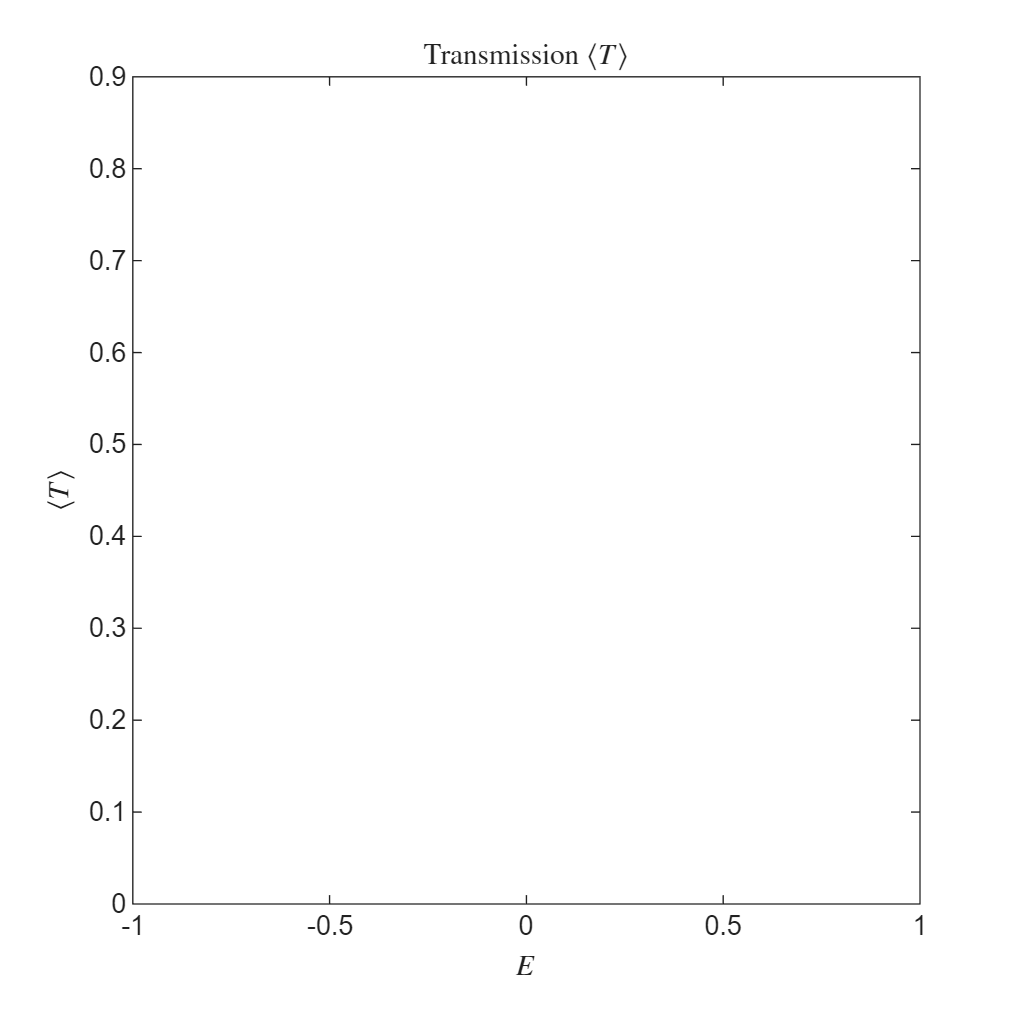

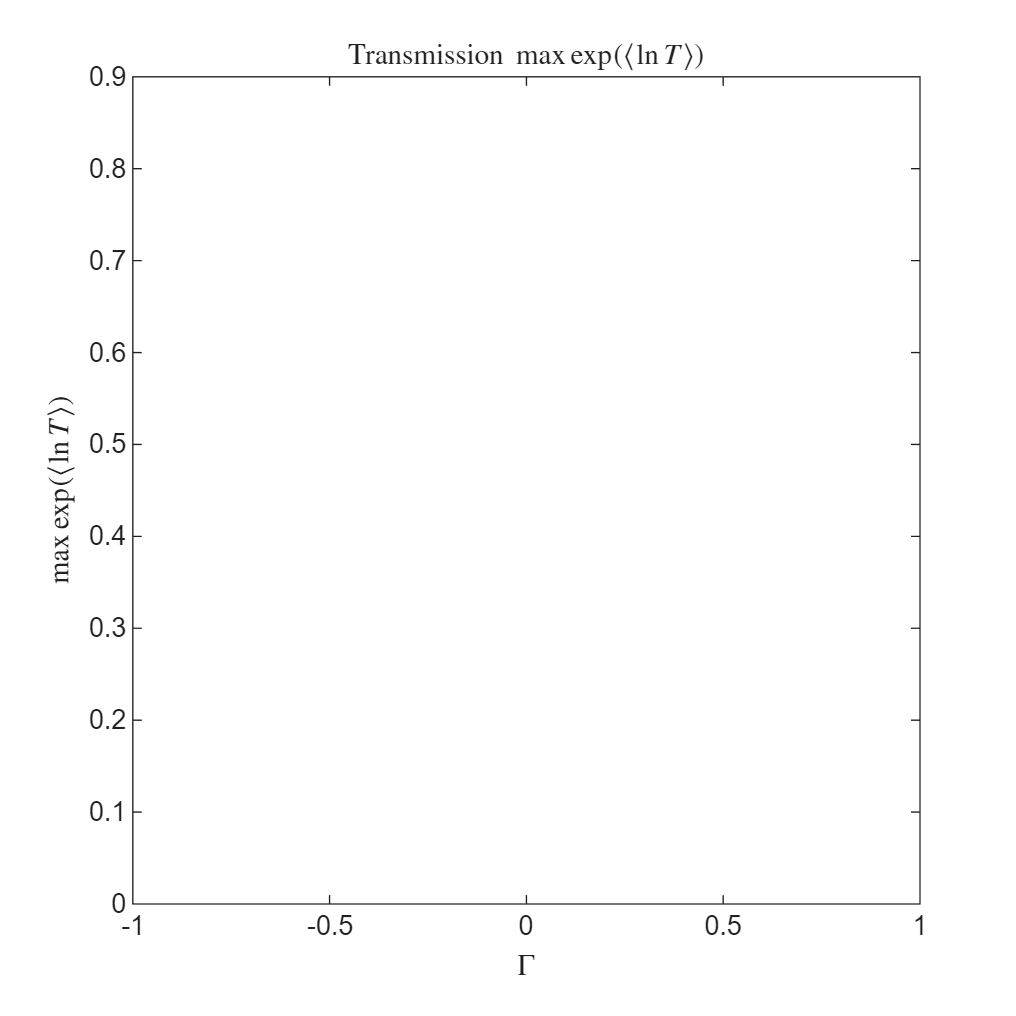

Localization length = 5.3333


Fit Localization length \langle\exp(\lnT)\rangle = 5.7317


Fit Localization length \langle T\rangle = 8.4508


    hold on
    ExplnT = exp(mean(log(Transmission(:,omega==0,:)),3));
    plot(Disorder, ExplnT,'+')
    if length(Disorder) > 1
        gaussEqn = 'exp(-(x/a)^2)';
        % gaussEqn = 'a/x';
        startPoints = [1];
        dis = 1;
        f = fit(Disorder(dis:end)', T_dis(dis:end),gaussEqn,'Start', startPoints)
        plot(Disorder(dis:end), f(Disorder(dis:end)))
    
        g = fit(Disorder(dis:end)', ExplnT(dis:end),gaussEqn,'Start', startPoints)
        plot(Disorder(dis:end), g(Disorder(dis:end)))
        xlabel('$\Gamma$','Interpreter','latex')
        legend({'$\max\langle T\rangle$','$\max\exp(\langle \ln T\rangle)$','Fit 1','Fit 2'},'Interpreter','latex')
    end
else
    % 变长度
    figure
    plot(omega, mean(Transmission,3))
    hold on
    xlabel('$E$','Interpreter','latex')
    title('Transmission $\langle T\rangle$','Interpreter','latex')
    ylabel('$\langle T\rangle $','Interpreter','latex')
    figure

    plot(omega, exp(mean(log(Transmission),3)))
    hold on
    xlabel('$\Gamma$','Interpreter','latex')
    ylabel('$\max\exp(\langle \ln T\rangle) $','Interpreter','latex')
    title('Transmission $\max\exp(\langle \ln T\rangle)$','Interpreter','latex')
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    figure
    T_dis = mean(Transmission(:,omega==0,:),3);

    plot(layer, T_dis,'o')
    xlabel('$L$','Interpreter','latex')
    title('Transmission $\max\langle T\rangle$','Interpreter','latex')
    ylabel('$\max\langle T\rangle $','Interpreter','latex')
    
    hold on
    ExplnT = exp(mean(log(Transmission(:,omega==0,:)),3));
    plot(layer, ExplnT,'+')
    yscale log

    eqn = 'exp(-x/a)';
    start = [1];
    dis = 1;
    f = fit(layer(dis:end)', T_dis(dis:end), eqn, "startpoint", start);
    plot(layer, f(layer))
    g = fit(layer(dis:end)', ExplnT(dis:end), eqn,'Start', start);
    plot(layer, g(layer))
    axis([0, max(layer), 0, 1])

    disp(['Localization length = ',num2str(12*4/Disorder^2)])
    disp(['Fit Localization length \langle\exp(\lnT)\rangle = ',num2str(g.a)])
    disp(['Fit Localization length \langle T\rangle = ',num2str(f.a)])
end

toc;

历时 330.064230 秒。


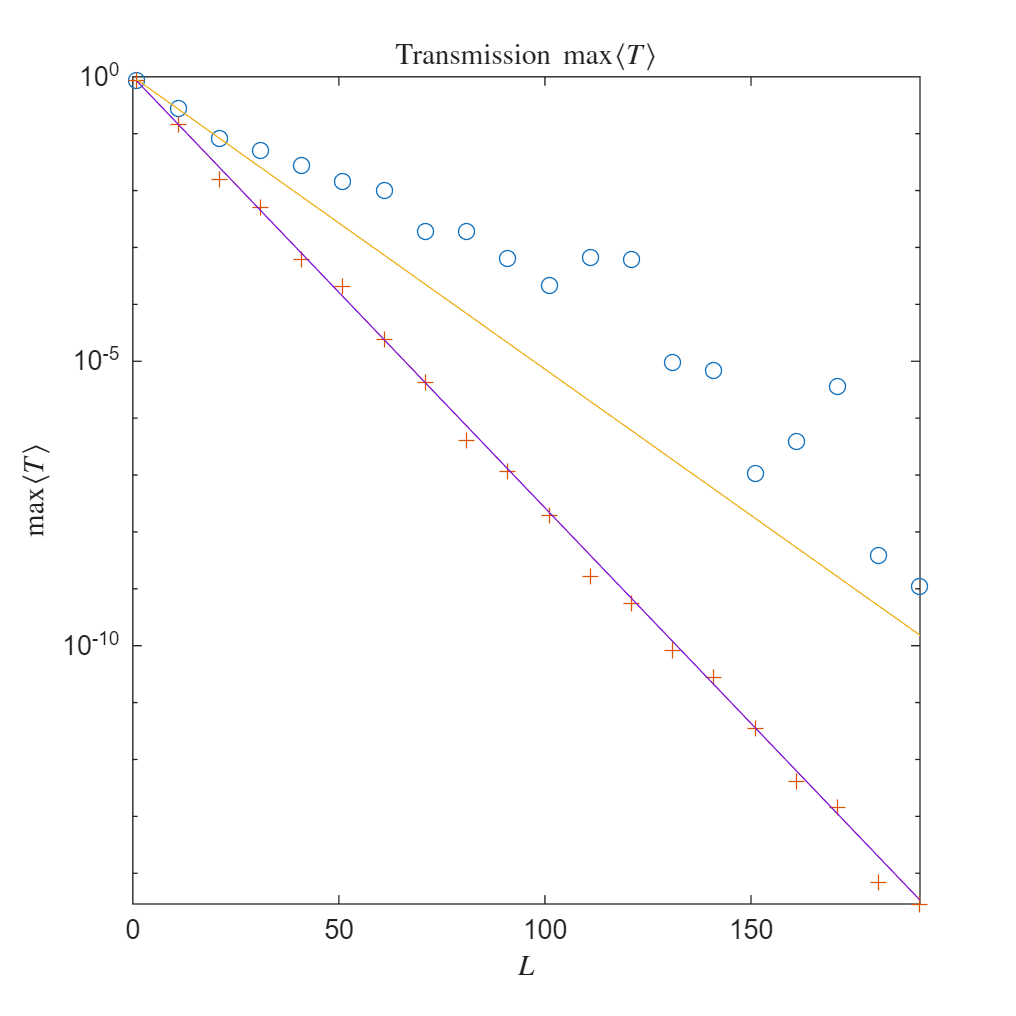







% yscale log
hold off

% %% Test example Energy band of periodic model
% kx = linspace(-pi,pi,N_point);
% energy_band = zeros(Width, length(kx));
% % 中心区哈密顿量，测试用例导线模型
% for ii = 1: length(kx)
%     Hk = H00 + V * exp(1i*kx(ii)) + V' * exp(-1i*kx(ii));
%     energy_band(:,ii) = eig(Hk);
% end
% subplot(1,2,1)
% plot(kx, energy_band);
% xlabel('k_x','Interpreter','tex')
% ylabel('Energy')






